### Include paths

addpath(genpath('lib'));
addpath(genpath('data'));
addpath('RIR_generator');
addpath('Exploration_scheme');
addpath('Echolocation');
addpath('Classification');

### Setup for RIR generator

%clearvars -except PCAFeatureMatrix
clearvars

% Utilise the stored training data
useStoredData = true;

% Defining room dimensions
RIRconstants = struct( ...
    'roomLength', 8*2, ...
    'roomWidth', 6*2, ...
    'roomHeight', 10, ...
    'robotPos', [4, 1, 4], ...
    'sampFreq', 24000, ...
    'AmountOfMicrophones', 6, ...
    'micRadius', 0.2, ...
    'SpeedofSound', 343, ...
    'micOffset', 30, ... # Notice that this is with respect to the global x-axis
    'directPathFlag', 0, ...
    'noiseWeighting', 1, ...
    'signalSDNR', 80, ...
    'signalSNR', repelem(100, 1, 6), ...
    'maximumDistance', 2, ...
    'minimumDistance', 0.5, ...
    'lengthBurst', 1500, ...
    'lengthSignal', 20000 ...
    );

setup = defaultMiscSetup([]);
setup = defaultSignalSetup(setup, RIRconstants);
setup = defaultArraySetup(setup, RIRconstants);
setup = defaultRirGenSetup(setup);
setup = defaultRoomSetup(setup, RIRconstants);
setup = defaultEmSetup(setup, RIRconstants);

setup.EM.noiseWeighting = RIRconstants.noiseWeighting;
setup.EM.plotIterations = 1; 
setup.EM.directPathFlag = RIRconstants.directPathFlag;
setup.signal.snr = RIRconstants.signalSNR;
setup.signal.sdnr = RIRconstants.signalSDNR;
setup.EM.maximumDistance = RIRconstants.maximumDistance;
setup.EM.nRefl = 1;
setup.EM.nIter = 20;

%plotRoom(setup);

### Setup for echolocation algorithm

% Struct for often used constants
echolocationConstants = struct( ...
    'Samplerate', RIRconstants.sampFreq, ...
    'AmountOfMicrophones', RIRconstants.AmountOfMicrophones, ...
    'UCARadius', RIRconstants.micRadius, ...
    'SpeedOfSound', RIRconstants.SpeedofSound, ...
    'AlphaOffset', RIRconstants.micOffset, ... 
    'AmountOfTaus', 301, ...
    'AmountOfPhis', 360, ...
    'AmountOfOmegas', 601 ...
    );

% Remark for echolocationConstants:
% AlphaOffset is an offset betweeen robots LOCAL x-axis and mic 1 in degrees, 
% and is thus not the same as RIRconstants.micOffset. However, they are equal in the
% beginning, assuming zero heading angle.


% Distance parameters
MinDistance = RIRconstants.minimumDistance;
MaxDistance = RIRconstants.maximumDistance;

% Calculate angular position of microphones
echolocationConstants.Betas = UCAangles(echolocationConstants.AmountOfMicrophones, echolocationConstants.AlphaOffset);

% Define linspaces for Phis, Taus, Omegas
Phis = linspace(0, deg2rad(359), echolocationConstants.AmountOfPhis); % In rad
Taus = linspace(MinDistance, MaxDistance, echolocationConstants.AmountOfTaus) * 2 / echolocationConstants.SpeedOfSound * echolocationConstants.Samplerate; % In samples
Omegas = ceil(linspace(0, echolocationConstants.Samplerate, echolocationConstants.AmountOfOmegas)); % In Hz
OmegasAngular = Omegas * 2 * pi; % In rad/sample
OmegasAngular(ceil(echolocationConstants.AmountOfOmegas/2+1):end) = OmegasAngular(ceil(echolocationConstants.AmountOfOmegas/2+1):end) - echolocationConstants.Samplerate * 2 * pi;

% Calculate angular position of microphones
echolocationConstants.Betas = UCAangles(echolocationConstants.AmountOfMicrophones, echolocationConstants.AlphaOffset);

% Find the beamformer weights
SteeringVectors = SteeringVector(Phis, OmegasAngular, echolocationConstants);

### Training data

classificationConstants = struct( ...
    'numTrainingPoints', 1000, ... % Should be even
    'numTestPoints', 60, ... % Should be even
    'numFeatures', 10, ... % This constant cannot be changed without changes in function CalculateFeatureVector
    'numPrincipalComponents', 3, ...
    'numNeighbours', 3 ...
    );

if ~exist("FeatureMatrix")
    if ~useStoredData
        FeatureMatrixTraining = ExtractFeatures(Taus, SteeringVectors, echolocationConstants, classificationConstants, RIRconstants, ...
            'Plot', true, 'Type', "Training");
        FeatureMatrixTraining = sortrows(FeatureMatrixTraining, 1);
        saveFeatureMatrix = FeatureMatrixTraining; % For saving
    else
        FeatureMatrixTraining = struct2array(load("Training_data/FeatureMatrix_1000_training_points_reflec.mat"));
        classificationConstants.numTrainingPoints = size(FeatureMatrixTraining, 1);
    end
end

minVals = zeros(1, classificationConstants.numFeatures);
maxVals = zeros(1, classificationConstants.numFeatures);
NormalisedFeatureMatrix = FeatureMatrixTraining;
for idx = 1 : classificationConstants.numFeatures
    minVals(idx) = min(NormalisedFeatureMatrix(:, idx+1));
    maxVals(idx) = max(NormalisedFeatureMatrix(:, idx+1));
    
    NormalisedFeatureMatrix(:, idx+1) = (NormalisedFeatureMatrix(:, idx+1) - minVals(idx)) ./ (maxVals(idx) - minVals(idx));
    %figure
    %plot(NormalisedFeatureMatrix(:, idx+1));
end

classificationConstants.minVals = minVals;
classificationConstants.maxVals = maxVals;

classificationConstants.TrainingFeatures = NormalisedFeatureMatrix;

### PCA Basis Transformation (Dimension Reduction)

% Standardizing the data by subtracting the mean of each feature
classificationConstants.featureMeans = mean(NormalisedFeatureMatrix(:, 2:end), 1);
NormalisedFeatureMatrix(:, 2:end) = NormalisedFeatureMatrix(:, 2:end) - classificationConstants.featureMeans;

% Finding the covariance matrix
CovMatrix = cov(NormalisedFeatureMatrix(:, 2:end));

% Extracting the eigenvectors of the covarinace matrix
[classificationConstants.EigenVectors, ~] = eigs(CovMatrix, classificationConstants.numPrincipalComponents);

% Performing the basis transformation by multiplying with the eigenvectors
PCAFeatureMatrix = zeros(classificationConstants.numTrainingPoints, classificationConstants.numPrincipalComponents+1);
PCAFeatureMatrix(:, 1) = NormalisedFeatureMatrix(:, 1);
PCAFeatureMatrix(:, 2:end) = NormalisedFeatureMatrix(:, 2:end) * classificationConstants.EigenVectors;

% Transferring data into the classificationConstants struct for later use
classificationConstants.PCATrainingFeatures = PCAFeatureMatrix;


%% Plotting Principal components
% Extracting eigenvalues from the covariance matrix
E = eigs(CovMatrix);

% Converting eigenvalues to variance
total_var = sum(E);

% Normalising the variances
variance = zeros(1, 6); % 6, because eigs by default returns 6 eigenvalues
for i = 1:length(E)
    variance(i) = E(i) / total_var;
end

% Plot the variances as a bar graph
%bar(variance);
%exportgraphics(gcf, 'testing_and_results\PCA_of_10Features.pdf', "ContentType", "vector")

clear minVals maxVals DiagEigenValues CovMatrix

### Classification evaluation

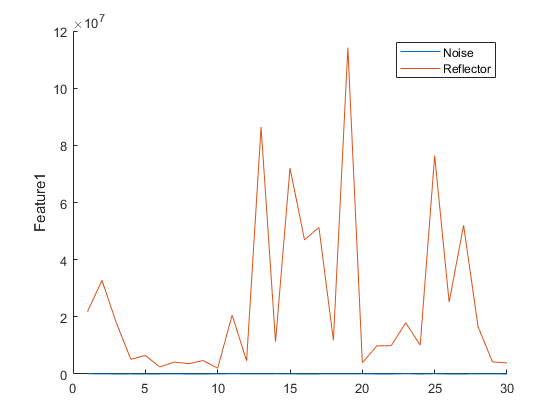

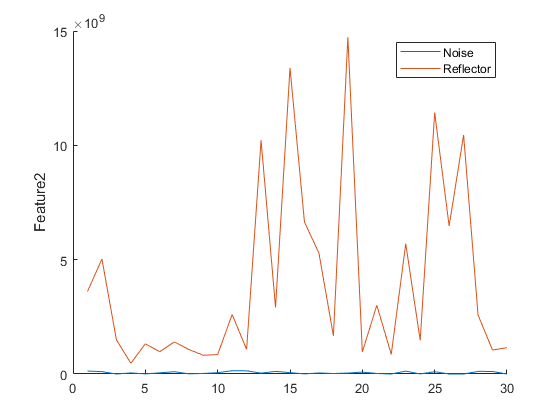

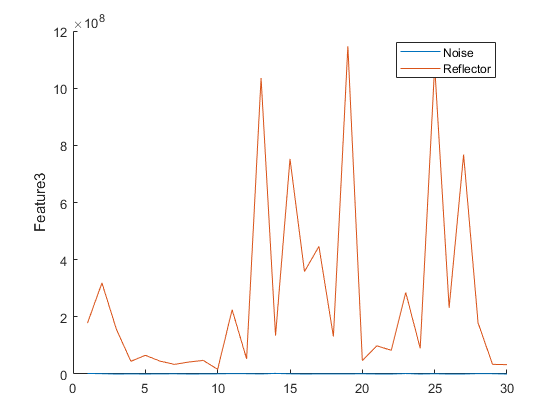

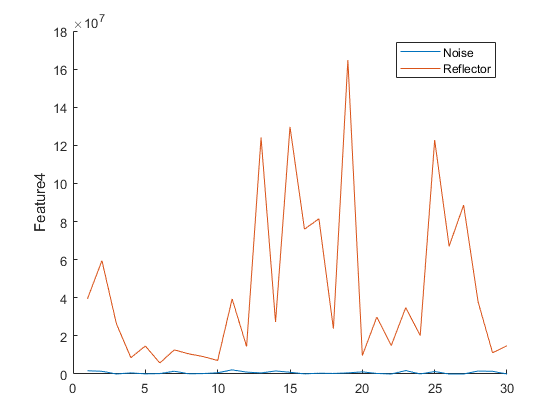

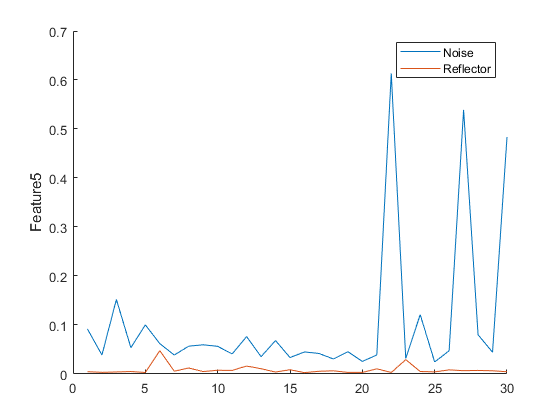

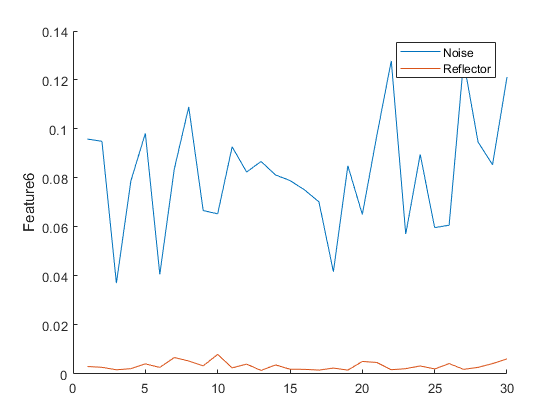

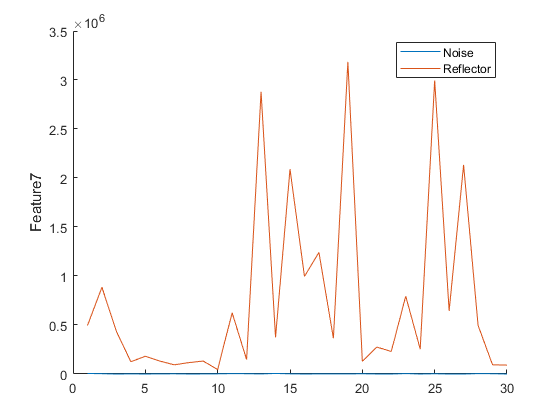

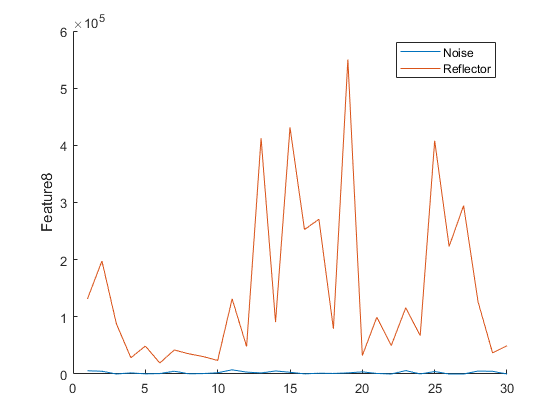

FeatureMatrixTest = ExtractFeatures(Taus, SteeringVectors, echolocationConstants, classificationConstants, RIRconstants, ...
            'Plot', false, 'Type', "Test");


TrainingClassification = FeatureMatrixTest(: , 1);
TestClassification = zeros(classificationConstants.numTestPoints,1);

for Idx = 1:classificationConstants.numTestPoints
    
    FeatureVector = FeatureMatrixTest(Idx, 2:end);
       
    FeatureVector = (FeatureVector - classificationConstants.minVals) ./ (classificationConstants.maxVals - classificationConstants.minVals);
    
    % Standardizing the data by subtracting the mean of each feature
    FeatureVector = FeatureVector - classificationConstants.featureMeans;    
    
    % Reducing dimensions using PCA
    PCAFeatureVector = FeatureVector * classificationConstants.EigenVectors;
    
    % KNN-search classification of PCA training data
    ClassIndices = knnsearch(classificationConstants.PCATrainingFeatures(:, 2:end), PCAFeatureVector, "K", classificationConstants.numNeighbours);
    ReflectorClass = sum(ClassIndices > classificationConstants.numTrainingPoints / 2) > classificationConstants.numNeighbours/2;
    
    TestClassification(Idx) = ReflectorClass;
    
end 

ConfusionMatrix = confusionmat(TrainingClassification,TestClassification)

ConfusionMatrix =     30     0
     0    30


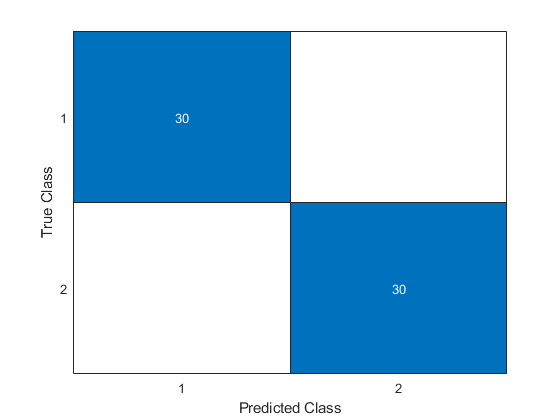

confusionchart(ConfusionMatrix)